# Performance of eigendecompositions

The questions that I would like to address in this script is of the performance of conducting eigenvalue decompositoin of a block matrix. In my Multi-scale Hessian Fracture Filtering (MSHFF) problem, we need to compute the eigenvalues and eigenvectors for every individual pixel (for 2D images), or voxel (3D images). The easies way to perform this computation is by using regular or nexted for loops. Although this approach is straight forward with code that is easily readable, it is not necesserily the most effecient computationally. In addition, given the large 3D arrays that represent microCT images of rocks, computations can take too long to complete. Here I try to probe this problem further to benchmark the performance of multiple methods of performing eignevalue decomposition of digital images.

## Comparing eigendecompsition of two matrices and a block matrix

- Change the edge length of the square matrices `A1` and `A2 by moving the sliders. `

- After you have decided on a size, click `Run` and the script will execute this section of the script. 

clearvars; home

showMatrices = false;
sizeA1 = 110;
sizeA2 = 150;
 

A1 = magic(sizeA1);
A2 = magic(sizeA2);
A = blkdiag(A1,A2);

t.a1.init = tic;
[A1eigvec, A1eigval] = eig(A1);
t.a1.end = toc(t.a1.init);
disp(['Eigendecomposition for A1 finished in ',num2str(t.a1.end),' secs']);

Eigendecomposition for A1 finished in 0.0051613 secs


t.a2.init = tic;
[A2eigvec, A2eigval] = eig(A2);
t.a2.end = toc(t.a2.init);
disp(['Eigendecomposition for A2 finished in ',num2str(t.a2.end),' secs']);

Eigendecomposition for A2 finished in 0.0089083 secs


disp(['A1 + A2 finished in ',num2str(t.a1.end + t.a2.end),' secs']);

A1 + A2 finished in 0.01407 secs


t.a.init = tic;
[Aeigvec, Aeigval] = eig(A);
t.a.end = toc(t.a.init);
disp(['Eigendecomposition for A finished in ',num2str(t.a.end),' secs']);

Eigendecomposition for A finished in 0.017879 secs



if showMatrices
    disp('Showing the eigenvectors'); %#ok<UNRCH> 
    A1eigvec
    A2eigvec
    Aeigvec
    
    disp('Showing the eigenvalues');
    A1eigval
    A2eigval
    Aeigval
    AAeigvec = blkdiag(A1eigvec,A2eigvec);
    AAeigval = blkdiag(A1eigval,A2eigval);
    
    eigvecRes = Aeigvec - AAeigvec
    eigvalRes = Aeigval - AAeigval
end

### Evaluating performance

Here, a sequence of operations are conducted while keeping track of the time needed. The primary variable is the size of the matrices. 

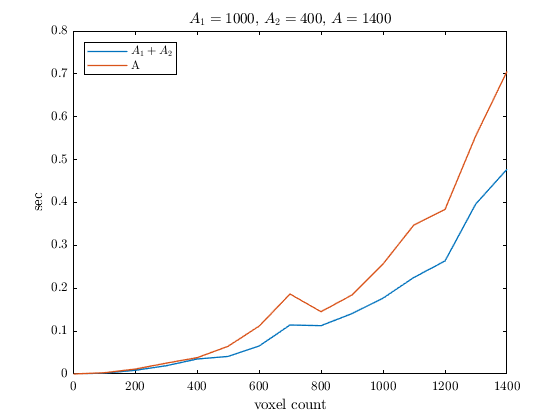

clearvars; home

maxSizeA1   = 1000;
maxSizeA2   = 400;
nSizes      =   15;
 

sizeA1 = fix(linspace(1,maxSizeA1,nSizes));
sizeA2 = fix(linspace(1,maxSizeA2,nSizes));

for j = 1:nSizes
    A1 = magic(sizeA1(j));
    A2 = magic(sizeA2(j));
    A  = blkdiag(A1,A2);
    t(j).a1.init = tic;
    [A1eigvec, A1eigval] = eig(A1);
    t(j).a1.end = toc(t(j).a1.init);
    t(j).a2.init = tic;
    [A2eigvec, A2eigval] = eig(A2);
    t(j).a2.end = toc(t(j).a2.init);
    t(j).a.init = tic;
    [Aeigvec, Aeigval] = eig(A);
    t(j).a.end = toc(t(j).a.init);
end

tmpA1  = [t(:).a1];
timeA1 = [tmpA1.end];
tmpA2  = [t(:).a2];
timeA2 = [tmpA2.end];
tmpA   = [t(:).a];
timeA  = [tmpA.end];

figure
% plot(sizeA1,timeA1,'DisplayName','$A_1$'); hold on;
% plot(sizeA2,timeA2,'DisplayName','$A_2$');
plot((sizeA1+sizeA2),timeA1+timeA2,'DisplayName','$A_1 + A_2$'); hold on;
plot((sizeA1+sizeA2),timeA, 'DisplayName','A');
title(['$A_1 = ', num2str(size(A1,1)),'$',...
       ', $A_2 = ', num2str(size(A2,1)),'$',...
       ', $A = ', num2str(size(A,1)),'$']);
ylabel('sec');
xlabel('voxel count');
legend('Location','northwest');

## Comparing the performance of eig() using for loop and a block sparse matrix

### Insuring both produce comparable results

the previous section compses a large block matrix from two larger full sub matrices. In our application, the large block matrix should be sparse with sub matrices that are either 2x2 or 3x3 along the diagonal.

clearvars
nVoxels = 821;
dimensions = 3;
 

Calculate the eigen values using a for loop

pix = cell(nVoxels,1);
for i = 1:nVoxels
    pix{i} = magic(dimensions);
end

t.forloop.init = tic;
for j = 1:nVoxels
    [result.forloop.pix.eigvec{j}, result.forloop.pix.eigval{j}] = eig(pix{j});
end
result.forloop.eigvec = blkdiag(result.forloop.pix.eigvec{:});
result.forloop.eigval = blkdiag(result.forloop.pix.eigval{:});
t.forloop.end = toc(t.forloop.init);
disp({'For loop'; ...
    ['Time = ',num2str(t.forloop.end),' secs']});

    {'For loop'            }
    {'Time = 0.030186 secs'}



Calculate the eigen values using a sparse matrix

Z = blkdiag(pix{:});
t.blockmatrix.init = tic;
[result.blockmatrix.eigvec,result.blockmatrix.eigval] = eig(Z);
t.blockmatrix.end = toc(t.blockmatrix.init);
disp({'Block matrix'; ...
    ['Time = ',num2str(t.blockmatrix.end),' secs']});

    {'Block matrix'      }
    {'Time = 2.6669 secs'}



Residuals

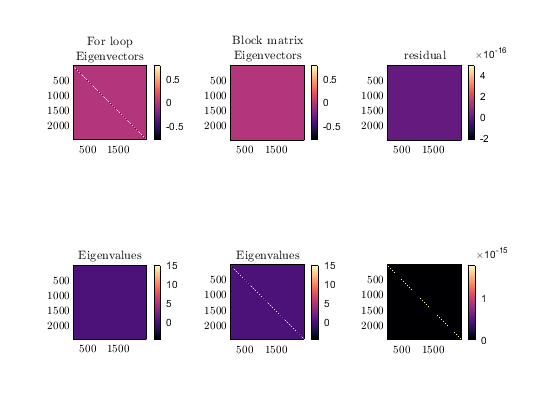

figure

subplot(2,3,1);
imagesc(result.forloop.eigvec);
axis square; colorbar
title({'For loop','Eigenvectors'});

subplot(2,3,4);
imagesc(result.forloop.eigval);
axis square; colorbar
title('Eigenvalues');

subplot(2,3,2);
imagesc(result.blockmatrix.eigvec);
title({'Block matrix','Eigenvectors'});
axis square; colorbar

subplot(2,3,5);
imagesc(result.blockmatrix.eigval);
title('Eigenvalues');
axis square; colorbar

subplot(2,3,3);
result.res.eigenvec = result.forloop.eigvec - result.blockmatrix.eigvec;
imagesc(result.res.eigenvec);
axis square; colorbar
title('residual');

subplot(2,3,6);
imagesc(result.forloop.eigval - result.blockmatrix.eigval);
axis square; colorbar

### Evaluating the performance by running a sequentially larger operations and measuring the time of completion

clearvars;
maxNVoxels = 3000000;
dimensions = 3;
nIncrements= 10;
nVoxels = fix(linspace(1,maxNVoxels,nIncrements));
performBlockOperation = false;
    

for k = 1:nIncrements
    pix = cell(nVoxels(k),1);
    for i = 1:nVoxels(k)
        pix{i} = rand(dimensions);
    end
    
    % parallel for loop
    t(k).parforloop.init = tic;
    tmpeigvec = cell(nVoxels(k),1);
    tmpeigval = cell(nVoxels(k),1);
    parfor j = 1:nVoxels(k)
        [tmpeigvec{j}, tmpeigval{j}] = eig(pix{j});
    end
    result.parforloop.pix.eigvec = tmpeigvec;
    result.parforloop.pix.eigval = tmpeigval;
    clear tmpeigval tmpeigvec;
    t(k).parforloop.end = toc(t(k).parforloop.init);
    
    % Regular for loop 
    t(k).forloop.init = tic;
    result.forloop.pix.eigvec = cell(1,nVoxels(k));
    result.forloop.pix.eigval= cell(1,nVoxels(k));
    for j = 1:nVoxels(k)
        [result.forloop.pix.eigvec{j}, result.forloop.pix.eigval{j}] = eig(pix{j});
    end
    t(k).forloop.end = toc(t(k).forloop.init);
    
    % Single block matrix
    % Perform this operation selectively because it is the slowest lof all of them.
    if performBlockOperation
        Z{k} = blkdiag(pix{:});
        t(k).blockmatrix.init = tic;
        [result.blockmatrix.eigvec,result.blockmatrix.eigval] = eig(Z{k});
        t(k).blockmatrix.end = toc(t(k).blockmatrix.init);
    else 
        t(k).blockmatrix.end = 0;
    end
    
    disp([num2str(k),'/',num2str(nIncrements),': completed in ',num2str(t(k).parforloop.end+t(k).forloop.end+t(k).blockmatrix.end),' secs']);
end

1/10: completed in 0.027416 secs
2/10: completed in 4.6025 secs
3/10: completed in 9.2133 secs
4/10: completed in 13.1041 secs
5/10: completed in 17.9743 secs
6/10: completed in 21.5471 secs
7/10: completed in 25.5184 secs
8/10: completed in 29.8481 secs
9/10: completed in 38.2464 secs
10/10: completed in 43.4425 secs


Plotting

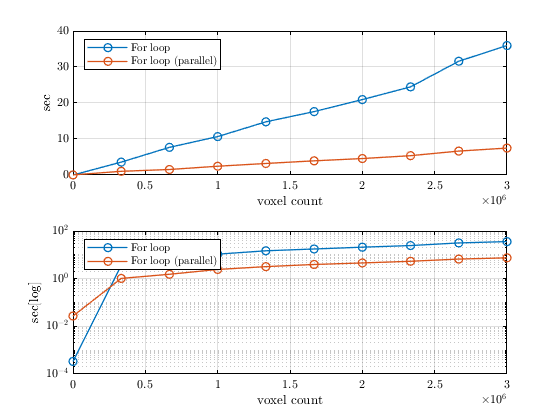

tmpParFor = [t(:).parforloop];
timeParFor = [tmpParFor.end];

tmpFor = [t(:).forloop];
timeFor = [tmpFor.end];

tmpBlk = [t(:).blockmatrix];
timeBlk = [tmpBlk.end];

figure
subplot(2,1,1);
plot(nVoxels,timeFor','-o','DisplayName','For loop'); hold on;
plot(nVoxels,timeParFor,'-o','DisplayName','For loop (parallel)');
if performBlockOperation, plot(nVoxels,timeBlk,'-o','DisplayName','Block');end
ylabel('sec');
xlabel('voxel count');
legend('Location','northwest');
grid on;

subplot(2,1,2);
semilogy(nVoxels,timeFor','-o','DisplayName','For loop'); hold on;
semilogy(nVoxels,timeParFor,'-o','DisplayName','For loop (parallel)');
if performBlockOperation, semilogy(nVoxels,timeBlk,'-o','DisplayName','Block');end
ylabel('sec[log]');
xlabel('voxel count');
legend('Location','northwest');
grid on;

## Conclusion

Creating a large block matrix from submatrices does not increase the performance of using the function `eig()` as we hoped. Instead, for loops seem to be a better candidate even though their performance is not optimal. I will consider using `parfor()` to parallize the operations.